x = load('Data16.mat')

x = struct with fields:
    X16: [57×16×1200 int64]


y = load('y16.mat');
data = x.X16;
for i = [1 length(data(1,1,:))]
    j = double(data(:,:,i));
    A(:,:, i) = corr(j);
    A(:,:,i) = A(:,:,i) - diag(diag(A(:,:,i)));
    A(isnan(A)) = 0;
end
sample = 6

sample = 6

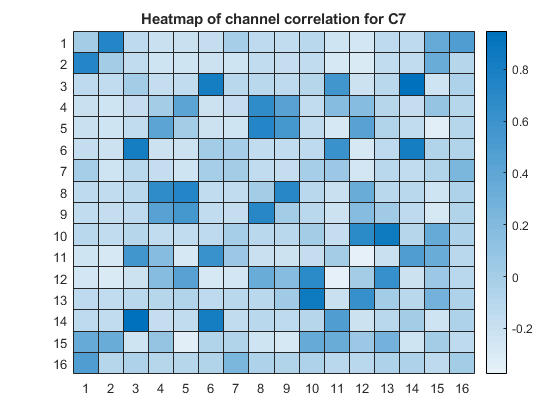

test = double(data(:,:,sample));
A_1 = corr(test);
A_1(isnan(A_1)) = 0;
T = 0.1;
A_1 = A_1 - diag(diag(A_1));
Atil_1 = A_1;
Atil_1(A_1 >= T ) = 1;
Atil_1(A_1 < T ) = 0;

heatmap(A_1)
title('Heatmap of channel correlation for C7')

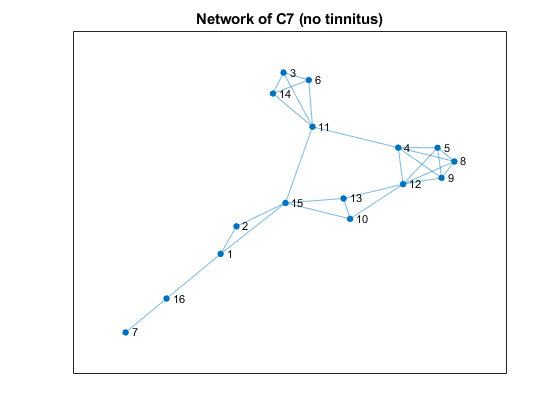


G_fed = graph(Atil_1, 'upper');
plot(G_fed)
title("Network of C7 (no tinnitus)")%  + sample)